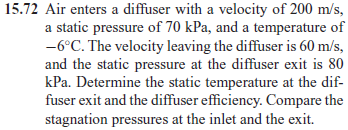

# RETIRED!!!!!

# classes

u = symunit;
air = ig;

# inflow properties

V1 = 200*u.m/u.s;
p1 = 70*u.kPa;
T1 = c2k(-6*u.Celsius);
M1 = simplify(V1/sqrt(air.gamma*air.R*T1));
po1 = combine(p1/air.p_po(M1));
po1_vpa = vpa(po1) %#ok

$$po1\_vpa = 90.024648000210050321822235007533\,\mathrm{kPa}$$

To1 = T1/air.T_To(M1);
clear po1_vpa;

# outflow properties

V2 = 60*u.m/u.s;
p2 = 80*u.kPa;
syms T2;
T2 = solve(air.cp*T1+V1^2/2 ==air.cp*T2+V2^2/2); % first law of thermodynamics
T2 = simplify(T2);
T2_vpa = vpa(T2) %#ok

$$T2\_vpa = 285.27749003984063745019920318725\,K$$

M2 = simplify(V2/sqrt(air.gamma*air.R*T2));
po2 = combine(p2/air.p_po(M2));
po2_vpa = vpa(po2)

$$po2\_vpa = 81.772639278985047207721605117614\,\mathrm{kPa}$$

To2 = T2/air.T_To(M2);
clear T2_vpa;